# Applied Linear Systems

## FINAL PROJECT

### submitted by: Karthik Balaji Keshavamurthi

### Table of Contents:

###                                 1. Introduction

###                                 2. Linear Quadratic Regulator Design

###                                 3. Simulation of Closed Loop System

###                                 4. Observability

###                                 5. Observer Design

###                                 6. Simulation of Augmented System

###                                 7. LQI Design

###                                 8. Construction of Connected System

###                                 9. Simulation of Integrated System

###                                10. Conclusion

## Introduction:

            In this final project, we will be developing a Luenberger State Estimator to estimate the states that cannot be measured such as $x_1 \;$or surge velocity (u), $x_{3\;}$or heave velocity (w) and $x_5$ or the pitch rate. We will estimate these states by using the outputs of the system x,z, and $\theta$ and comparing with the outputs of the observer system, i.e $\hat{x}$, $\hat{z}$ and $\theta^ˆ$ to generate the estimated states. After this, we will design the controller by optimal control using Linear Quadratic Regulator (LQR) strategy. We will be estimating the weights based on the Maximum control Effort Constraint and also based on the settling time. Finally, we also design the controller using LQI and create a connected final system and check if the AUV enters the tunnel with only 0.5m clearance.  

clear 
close all
clc

First we have to export the ss file.

original_system = load("open_loop_system.mat");
original_system = original_system.original_system;

Let us get the A,B,C and D matrices.

A_matrix = original_system.A;
B_matrix = original_system.B;
C_matrix = original_system.C;
D_matrix = original_system.D;
initial_condition_vector = [100,-415,-300,200,0,45*pi/180]';


## Problem 1.1- LQR Design:

We will estimate the weights in the Q and R matrix iteratively based on the Simulation results from 1.2. The weights have to be output weighed as we do not have access to all the states. The variables q1, q2 and q3 are the weights corresponding to x,z and $\theta$. We can directly add weights in this manner as our output is directly the state value. If that was not the case, then we would have to multiply in the form $C^T *Q^* *C$ , where $Q^*$ is the output weighing 3x3 matrix. The variables r1,r2, and r3 are the control input weights. 

r1 = 45;
r2 = 35;
r3 = 3;
q1 = 60077500*r1;
q2 = 365550000*r2;
q3 = 9100000000000*r3;
Q = diag([0,q1,0,q2,0,q3])

Q = 	1.0e+13 *

         0         0         0         0         0         0
         0    0.0003         0         0         0         0
         0         0         0         0         0         0
         0         0         0    0.0013         0         0
         0         0         0         0         0         0
         0         0         0         0         0    2.7300


R = diag([r1,r2,r3])

R =     45     0     0
     0    35     0
     0     0     3


[G,S,P] = lqr(original_system,Q,R);

## 1.2 : Simulation of Closed Loop system

Ac = A_matrix - (B_matrix * G);
new_sys = ss(Ac,zeros(6,3),C_matrix,zeros(3,3));
[y, t, x] = initial(new_sys,initial_condition_vector);
pos_x = y(:,1)+465;
pos_z = y(:,2)+150;
theta = y(:,3);
input = -G*(x');
maxinput1 = max(abs(input(1,:))) *10/10;
maxinput2 = max(abs(input(2,:))) *10/10;
maxinput3 = max(abs(input(3,:))) *10/10;
table(maxinput1,maxinput2,maxinput3,'VariableNames',...
    {'Max Control1', 'Max Control2','Max Control3'})

ans = 1×3 table
    Max Control1    Max Control2    Max Control3
    ____________    ____________    ____________

     2.9429e+06      2.9794e+06      2.6642e+06 


As we can see all the control inputs are within the 3e6N threshold. I was able to attain the 10% control input only to Control Inputs 1 and 2, but not to 3. 

s = lsiminfo(y,t,'SettlingTimeThreshold',0.05);
settling_time = [s(1).SettlingTime,s(2).SettlingTime,s(3).SettlingTime];
output_names = {'Position-x', 'Position-y','Pitch Angle'};
table(output_names',settling_time','VariableNames',{'Output Type', '5% Settling Time'})

ans = 3×2 table
      Output Type      5% Settling Time
    _______________    ________________

    {'Position-x' }         0.73761    
    {'Position-y' }         0.33596    
    {'Pitch Angle'}        0.028527    


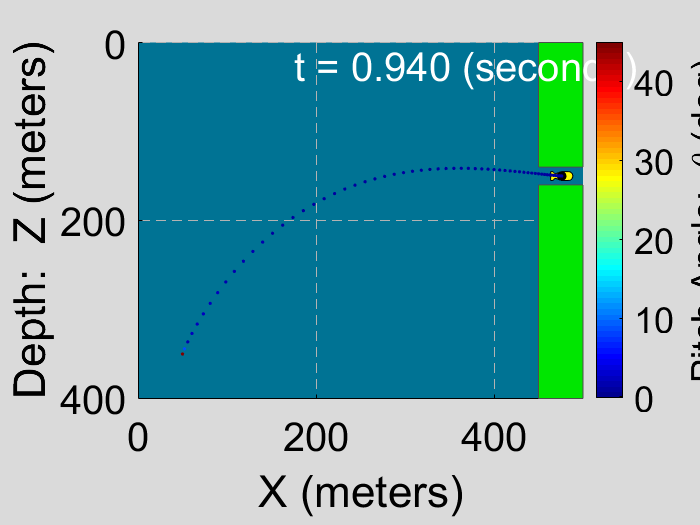

animate_auv(t(1:60,1),pos_x(1:60,1),pos_z(1:60,1),theta(1:60,1))

 We also have to plot the response. 

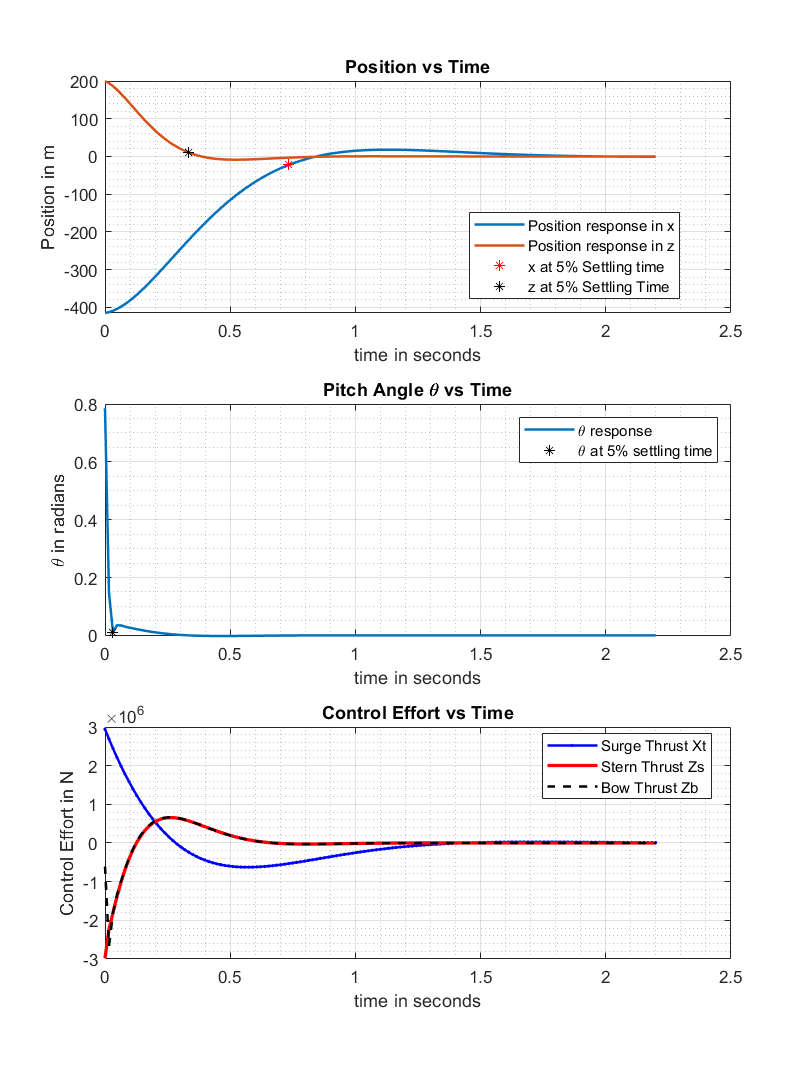


[~,index_output1] = min(abs(t - s(1).SettlingTime));
[~,index_output2] = min(abs(t - s(2).SettlingTime));
[~,index_output3] = min(abs(t - s(3).SettlingTime));


% Now we plot the graphs. The x and z have the same units and hence will be
% plot in the same graph. 
figure(1)
figure('Position',[10,10,900,1200])
subplot(3,1,1)

plot(t,y(:,1:2),'linewidth',1.5)
title('Position vs Time')
grid on
grid minor
hold on
plot(t(index_output1,1),y(index_output1,1),'r*')
hold on 
plot(t(index_output2,1),y(index_output2,2),'k*')
xlabel('time in seconds')
ylabel('Position in m')
leg=legend('Position response in x', 'Position response in z',...
    'x at 5% Settling time','z at 5% Settling Time');
set(leg,'location','best')

subplot(3,1,2)
plot(t, y(:,3),'linewidth',1.5)
hold on
grid on
grid minor
plot(t(index_output3,1),y(index_output3,3),'k*')
title('Pitch Angle \theta vs Time')
legend('\theta response','\theta at 5% settling time')
xlabel('time in seconds')
ylabel('\theta in radians')

subplot(3,1,3)
plot(t', input(1,:),'.-b','linewidth',1.5)
title('Control Effort vs Time')
grid on
grid minor
hold on
plot(t', input(2,:),'r','linewidth',2)
plot(t', input(3,:),'--k','linewidth',1.5)
xlabel('time in seconds')
ylabel('Control Effort in N')
leg=legend('Surge Thrust Xt', 'Stern Thrust Zs','Bow Thrust Zb');
set(leg,'location','best')

## Problem 2 - Observabilty

We will have to find the Observability matrix 'O' and check for its rank. I have made a conditional statement for this purpose.

O =  obsv(A_matrix,C_matrix);

if rank(O) == size(A_matrix,1)
    % This means that Matrix is Observable. If condition is satisfied,
    % the following statement would be the output
    disp('Matrix is Completely Observable')  
else
    % If the rank is not full, the following statement will be the output.
    disp('Matrix is not Completely Observable')
end

Matrix is Completely Observable


We can see from the output that the matrix is completely controllable. Now, we will check if any subset is completely controllable. 

To accomplish this, we will take two of the three columns of B matrix to check if any of the inputs are redundant. 

**Case 1: **Only XT and Zs are considered, i.e Columns 1 and 2 only

O =  obsv(A_matrix,C_matrix(1:2,:))';

if rank(O) == size(A_matrix,1)
    % This means that Matrix is Observable. If condition is satisfied,
    % the following statement would be the output
    disp('Matrix is Completely Observable')  
else
    % If the rank is not full, the following statement will be the output.
    disp('Matrix is not Completely Observable')
end

Matrix is not Completely Observable


**Case 2: **Only Zs and Zb are considered, i.e Columns 2 and 3 only

O =  obsv(A_matrix,C_matrix(2:3,:))';

if rank(O) == size(A_matrix,1)
    % This means that Matrix is Observable. If condition is satisfied,
    % the following statement would be the output
    disp('Matrix is Completely Observable')  
else
    % If the rank is not full, the following statement will be the output.
    disp('Matrix is not Completely Observable')
end

Matrix is not Completely Observable


**Case 3: **Only XT and Zb are considered, i.e Columns 1 and 3 only

O =  obsv(A_matrix,C_matrix([1,3],:))';

if rank(O) == size(A_matrix,1)
    % This means that Matrix is Observable. If condition is satisfied,
    % the following statement would be the output
    disp('Matrix is Completely Observable')  
else
    % If the rank is not full, the following statement will be the output.
    disp('Matrix is not Completely Observable')
end

Matrix is not Completely Observable


From these three cases, we can clearly see that no subsets of the Control Inputs can make the system **Completely Observable.**

## Problem 3.1 - Observer Design:

We will design a Luenbergen observer to estimate the states that cannot be measured. For this, we will have to initiate a set of poles.

observer_poles = [-50,-55,-45,-75,-60,-55];
K_gain = place(A_matrix', C_matrix', observer_poles)'

K_gain = 	1.0e+03 *

    2.4586   -0.0188    0.0436
    0.0998   -0.0003    0.0008
   -0.0248    3.4605   -0.8064
   -0.0004    0.1188   -0.0127
    0.0427   -0.5366    3.4669
    0.0008   -0.0094    0.1193


observer_system = ss((A_matrix-(K_gain*C_matrix)),zeros(6,3),C_matrix,zeros(3,3));

Now we will plot the Poles of the Open-loop, LQR based Closed-loop and Observer system using the pzmap function of matlab

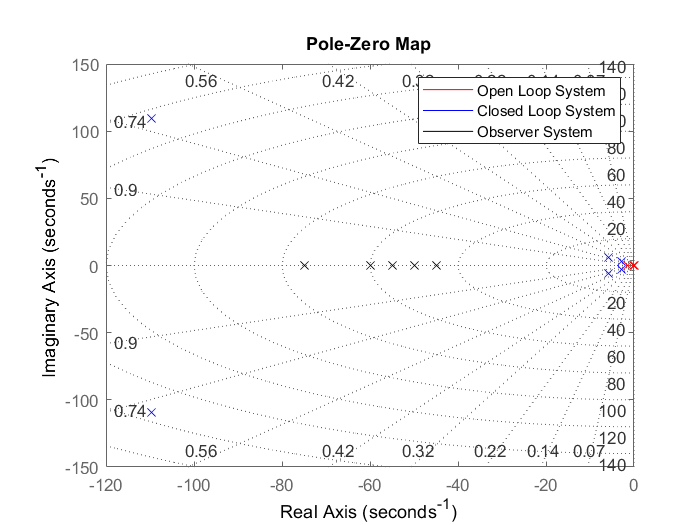

figure(3)
pzmap(original_system,'r',new_sys,'b',observer_system,'k')
sgrid
axis equal
xlim([-120,0])
legend('Open Loop System', 'Closed Loop System','Observer System')
grid on

## Problem 3.2 - Simulation of Augmented System:

% First we need to create the Augment matrices for both cases.
% Case 1 -  G = zeros
% Case 2 -  G = Closed Loop Gain Matrix.
G_openloop = zeros(size(G));
% Augmented Matrix1 
Augmented_matrix_1A = [A_matrix,((-1).*(B_matrix * G_openloop));...
    (K_gain *C_matrix),(A_matrix - (K_gain*C_matrix) - (B_matrix*G_openloop))];
Augmented_matrix_2A = [A_matrix,(-1.*B_matrix * G);...
    (K_gain *C_matrix),(A_matrix - (K_gain*C_matrix) - (B_matrix*G))];
Augmented_matrix_1C = [C_matrix, (-D_matrix * G_openloop);...
    zeros(size(C_matrix)),(C_matrix-(D_matrix*G_openloop))];
Augmented_matrix_2C = [C_matrix, (-D_matrix * G);...
    zeros(size(C_matrix)),(C_matrix-(D_matrix*G))];
only_observer_system = ss(Augmented_matrix_1A,[],Augmented_matrix_1C,[]);
feedback_observer_system = ss(Augmented_matrix_2A,[],Augmented_matrix_2C,[]);
initial_condition_observer = [0,-465,0,-150,0,0]';
initial_condition_only_observer = [initial_condition_vector;initial_condition_observer];
% First we simulate for Observer:
sim_time = 0.2;
[y_observer, t_observer, x_observer] = initial(only_observer_system,...
    initial_condition_only_observer,sim_time);
% The initial condition of second stage is the final state at t = sim_time
[y_feedback,t_feedback,x_feedback] = initial(feedback_observer_system,(x_observer(end,:))');


#### Appending the vectors:

t_final = [t_observer;((t_feedback(2:end,1))+sim_time)];

pos_x_hat_final = [y_observer(:,4)+465;(y_feedback(2:end,4)+ 465)] ;
pos_z_hat_final = [y_observer(:,5)+150;(y_feedback(2:end,5)+ 150)] ;
theta_hat_final = [y_observer(:,6);(y_feedback(2:end,6))] ;
pos_x_final = [y_observer(:,1)+465;(y_feedback(2:end,1)+ 465)] ;
pos_z_final = [y_observer(:,2)+150;(y_feedback(2:end,2)+ 150)] ;
theta_final = [y_observer(:,3);(y_feedback(2:end,3))] ;
input1 = -G * (x_feedback(:,7:12)');
maxinput1obs = max(abs(input1(1,2:end))) *10/10;
maxinput2obs = max(abs(input1(2,2:end))) *10/10;
maxinput3obs = max(abs(input1(3,2:end))) *10/10;
disp(table(maxinput1obs,maxinput2obs,maxinput3obs,'VariableNames',...
    {'Max Control1', 'Max Control2','Max Control3'}))

    Max Control1    Max Control2    Max Control3
    ____________    ____________    ____________

     2.5567e+06      1.4552e+06      2.8517e+06 



We can see from the above table that the maximum of all three inputs lie within the **3e6 N** threshold. Now let us find the settling time for the actual outputs of the system.

s1 = lsiminfo(y_feedback(:,1:3),t_feedback,'SettlingTimeThreshold',0.05);
settling_time1 = [s1(1).SettlingTime,s1(2).SettlingTime,s1(3).SettlingTime];
output_names = {'Position-x', 'Position-y','Pitch Angle'};
disp(table(output_names',settling_time1','VariableNames',...
    {'Output Type', '5% Settling Time in s'}))

      Output Type      5% Settling Time in s
    _______________    _____________________

    {'Position-x' }           0.73743       
    {'Position-y' }           0.33192       
    {'Pitch Angle'}          0.024761       



We can see that all three settling times are within the **1 second** threshold.

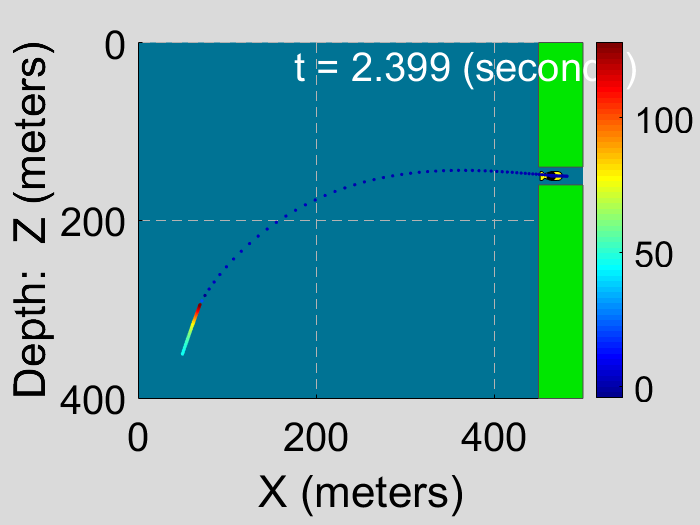

animate_auv(t_final,pos_x_final,pos_z_final,theta_final)

% we need to find the index of settling time to find output values
[~,index_output1] = min(abs(t_feedback - s1(1).SettlingTime));
[~,index_output2] = min(abs(t_feedback - s1(2).SettlingTime));
[~,index_output3] = min(abs(t_feedback - s1(3).SettlingTime));

Now we will plot the response

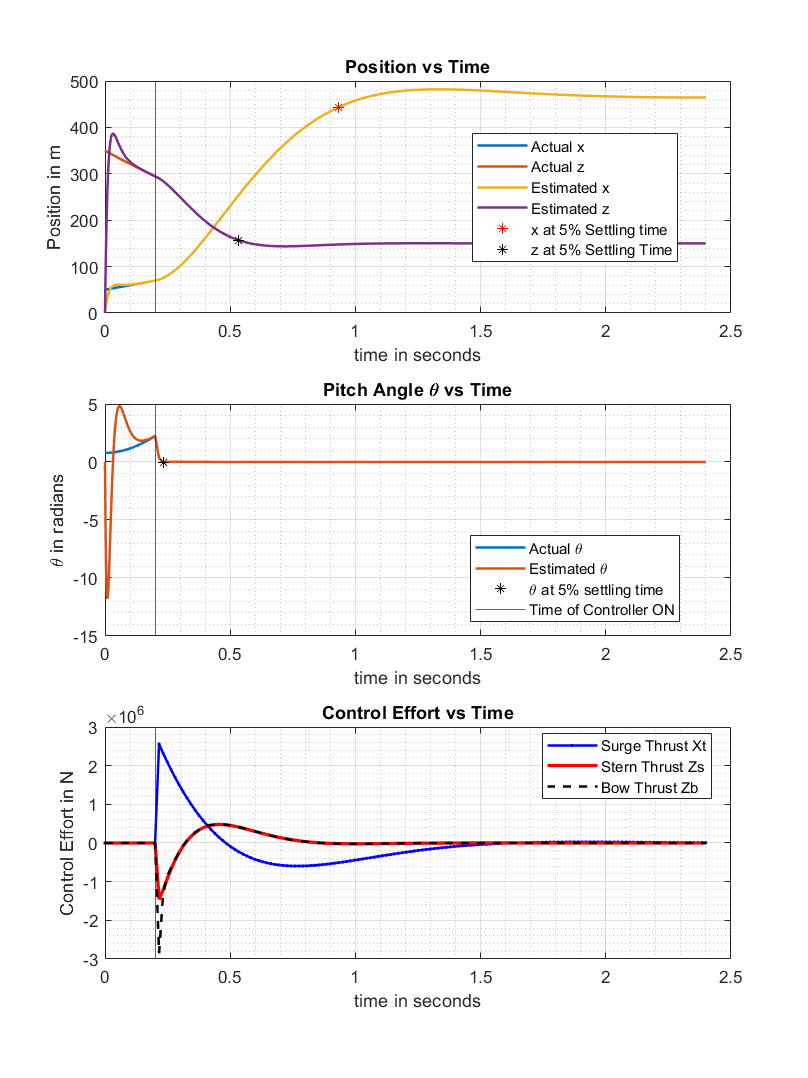

% Now we plot the graphs. The x and z have the same units and hence will be
% plot in the same graph. 
figure(3)
figure('Position',[10,10,900,1200])
subplot(3,1,1)

plot(t_final,pos_x_final,'linewidth',1.5)
title('Position vs Time')
grid on
grid minor
hold on
plot(t_final,pos_z_final,'linewidth',1.5)
plot(t_final,pos_x_hat_final,'linewidth',1.5)
plot(t_final,pos_z_hat_final,'linewidth',1.5)
plot(t_feedback(index_output1,1)+ sim_time,y_feedback(index_output1,1)+465,'r*')
plot(t_feedback(index_output2,1)+ sim_time,y_feedback(index_output2,2)+150,'k*')
xline(sim_time);
xlabel('time in seconds')
ylabel('Position in m')
leg=legend('Actual x', 'Actual z',...
    'Estimated x', 'Estimated z',...
    'x at 5% Settling time','z at 5% Settling Time');
set(leg,'location','best')
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
subplot(3,1,2)
plot(t_final, theta_final,'linewidth',1.5)
hold on
grid on
grid minor
plot(t_final, theta_hat_final,'linewidth',1.5)
plot(t_feedback(index_output3,1)+ sim_time,...
    y_feedback(index_output3,3),'k*')
title('Pitch Angle \theta vs Time')
xline(sim_time);
leg = legend('Actual \theta','Estimated \theta',...
    '\theta at 5% settling time','Time of Controller ON');
xlabel('time in seconds')
ylabel('\theta in radians')
set(leg,'location','best')
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
subplot(3,1,3)
control_null = zeros(size(t_observer));
control1 = [control_null;input1(1,2:end)'];
control2 = [control_null;input1(2,2:end)'];
control3 = [control_null;input1(3,2:end)'];
plot(t_final,control1,'.-b','linewidth',1.5)
title('Control Effort vs Time')
grid on
grid minor
hold on
plot(t_final,control2,'r','linewidth',2)
plot(t_final,control3,'--k','linewidth',1.5)
xline(sim_time);
xlabel('time in seconds')
ylabel('Control Effort in N')
leg=legend('Surge Thrust Xt', 'Stern Thrust Zs','Bow Thrust Zb');
set(leg,'location','best')

The Black vertical line in the Plot at 0.2 seconds is the instant when the controller is turned on. 

You can see that the control inputs upto the point are 0.

## Problem 4.1 - LQI Design:

Now we will add Intergral Control to the system. For this, the Gain matrix is a set of integral gains for the number of Outputs, i.e 3. 

Hence, our final number of states in the system for LQI is 9. 

Q_I1 = q1*10;
Q_I2 = q2*1700;
Q_I3 = q3.*15;
Q_I = diag([Q_I1,Q_I2,Q_I3]);

LQI_Qmat = [Q, zeros(6,3);zeros(3,6),Q_I]; %9x9 matrix

% The LQI gain contains both GO and GI ,i.e State gain and Integral Gain.
[LQI_gain,Solution,LQI_poles] = lqi(original_system,LQI_Qmat,R.*2);
G0 = LQI_gain(:,1:6);
GI = LQI_gain(:,7:end);

## Problem 4.2 - Construction of Connected System:

Now we will construct the LTI objects for all the subsystems that we can find from the below diagram.

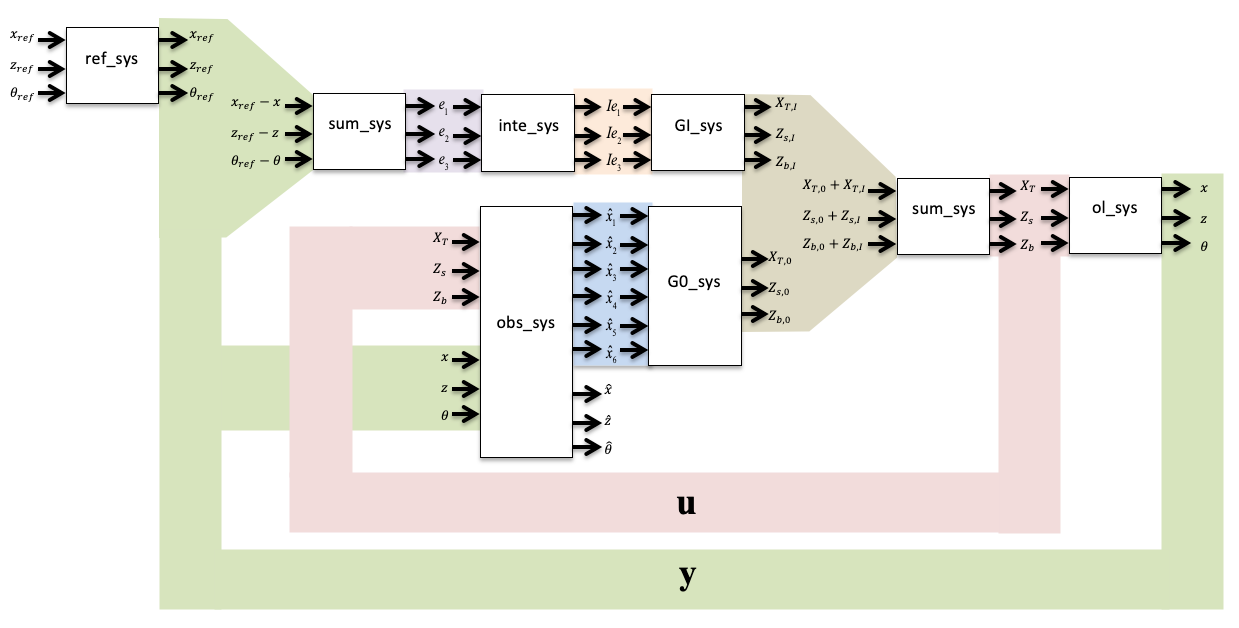

### **1. Reference System (ref_sys):**

**Inputs: **x_ref, z_ref and theta_ref

**Outputs: **x_ref, z_ref and theta_ref 

ref_sys = tf(eye(3));
set(ref_sys,'inputname',{'x_ref','z_ref', 'theta_ref'},...
    'outputname',{'x_ref','z_ref', 'theta_ref'});


### **2. Sum System (sum_sys_1):**

**Inputs: **x_ref - x, z_ref - z and theta_ref - theta

**Outputs: **e1, e2 and e3

sum_sys_1 = tf(eye(3));
set(sum_sys_1,'inputname',{'x_ref - x',...
    'z_ref - z', 'theta_ref - theta'},...
    'outputname',{'e1','e2', 'e3'});


### **3. integrator System (Inte_sys):**

**Inputs: **e1, e2 and e3

**Outputs: I**e1, Ie2 and Ie3

inte_sys = tf(num2cell(eye(3)),[1 0]);
set(inte_sys,'inputname',{'e1','e2', 'e3'},...
    'outputname',{'Ie1','Ie2', 'Ie3'});

### **4. integral Control System (GI_sys):**

**Inputs: I**e1, Ie2 and Ie3

**Outputs: **XT,I, Zs,I and Zb,I

GI_sys = tf(-GI);
set(GI_sys,'inputname',{'Ie1','Ie2', 'Ie3'},...
    'outputname',{'XT,I','Zs,I', 'Zb,I'});

### **5.Sum System (sum_sys_2):**

**Inputs: **XT,I + XT,0, Zs,I + Zs,0 and Zb,I + Zb,0

**Outputs: **XT, Zs and Zb

sum_sys_2 = tf(eye(3));
set(sum_sys_2,'inputname',{'XT,I + XT,0',...
    'Zs,I + Zs,0', 'Zb,I + Zb,0'},...
    'outputname',{'XT','Zs', 'Zb'});

### **6.Open Loop System (ol_sys):**

**Inputs: **XT, Zs and Zb

**Outputs: **x, z and theta

ol_sys = original_system;
set(ol_sys,'InputName',{'XT','Zs','Zb'})
set(ol_sys,'OutputName',{'x','z','theta'})


### **7.Observer System (obs_sys):**

**Inputs: **XT, Zs, Zb, x, z and theta

**Outputs: **$\hat{x_1 } \;,\hat{x_2 } \;,\hat{x_3 } \;,\hat{x_4 } \;,\hat{x_5 } \;,\hat{x_6 } \;,\hat{x} ,\hat{z} \;\textrm{and}\;\theta^ˆ$

#### **Construction of State Space:**

            This system takes 6 inputs which are the control forces and also the output. The states are the estimated states (6 states).

Hence, A matrix of this system is a 6x6 matrix of  $A_{\textrm{openloop}} -\left(K_{\textrm{observer}} \;\ldotp C_{\textrm{openloop}} \right)$.

B Matrix is the appended matrix of B_openloop and a 6x3 matrix of $K_{\textrm{observer}}$ . 

C Matrix is a 9x6 matrix. This is because we have 9 outputs. 

D Matrix is a 9x6 matrix of 0s. 

A_obs = A_matrix -(K_gain*C_matrix)

A_obs = 	1.0e+03 *

   -0.0002   -2.4586         0    0.0188         0   -0.0436
    0.0010   -0.0998         0    0.0003         0   -0.0008
         0    0.0248   -0.0008   -3.4605   -0.0017    0.8064
         0    0.0004    0.0010   -0.1188         0    0.0127
         0   -0.0427   -0.0003    0.5366   -0.0010   -3.4669
         0   -0.0008         0    0.0094    0.0010   -0.1193


B_obs = [B_matrix,K_gain]

B_obs = 	1.0e+03 *

    0.0000         0         0    2.4586   -0.0188    0.0436
         0         0         0    0.0998   -0.0003    0.0008
         0    0.0000    0.0000   -0.0248    3.4605   -0.8064
         0         0         0   -0.0004    0.1188   -0.0127
         0    0.0000   -0.0000    0.0427   -0.5366    3.4669
         0         0         0    0.0008   -0.0094    0.1193



C_obs = [eye(6);C_matrix]

C_obs =      1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     1     0     0     0
     0     0     0     1     0     0
     0     0     0     0     1     0
     0     0     0     0     0     1
     0     1     0     0     0     0
     0     0     0     1     0     0
     0     0     0     0     0     1



D_obs = zeros(9,6)

D_obs =      0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0



obs_sys = ss(A_obs,B_obs,C_obs,D_obs);
set(obs_sys,'InputName',{'XT','Zs','Zb', 'x','z','theta'})
set(obs_sys,'OutputName',{'x1_hat','x2_hat','x3_hat','x4_hat',...
    'x5_hat','x6_hat' ,'x_hat','z_hat','theta_hat'})
set(obs_sys,'StateName',{'x_dot_hat','x-hat','z-dot_hat',...
    'z-hat','theta_dot_hat','theta_hat'});

### **9.Feedback Controller System (G0_sys):**

**Inputs:  **$\hat{x_1 } \;,\hat{x_2 } \;,\hat{x_3 } \;,\hat{x_4 } \;,\hat{x_5 } \;\;\;\textrm{and}\;\;\hat{x_6 }$

**Outputs: **$X_{T,0} \;,Z_{s,0} \;\;,\textrm{and}\;Z_{b,0}$

G0_sys = tf(-G0);
set(G0_sys,'inputname',{'x1_hat','x2_hat','x3_hat',...
    'x4_hat','x5_hat','x6_hat'},...
    'outputname',{'XT,0','Zs,0', 'Zb,0'});


### **Construction of System using Append:**

Now we will use Append and connect to connect all these 8 systems together to get one integrated system

sys = append(ref_sys,sum_sys_1,inte_sys,GI_sys,sum_sys_2,ol_sys,obs_sys,G0_sys);

Now we construct the Connectivity Matrix:

%The inputs are the refeference signals
inputs = [1,2,3]; 
%The outputs are actual outputs, estimated outputs and controller effort
outputs = [13,14,15,16,17,18,25,26,27];
Q_connect = [4,1,-16;5,2,-17;6,3,-18;7,4,0;8,5,0;9,6,0;...
    10,7,0;11,8,0;12,9,0;13,10,28;14,11,29;15,12,30;...
             16,13,0;17,14,0;18,15,0;19,13,0;20,14,0;21,15,0;...
             22,16,0;23,17,0;24,18,0;25,19,0;26,20,0;...
             27,21,0;28,22,0;29,23,0;30,24,0];

**Let us create the final system using the connect function:**

closed_loop_system = connect(sys,Q_connect,inputs,outputs);

## Problem 4.3 - Simulation of Integrated System:

Lets create a time vector and three reference vectors of the same size. 

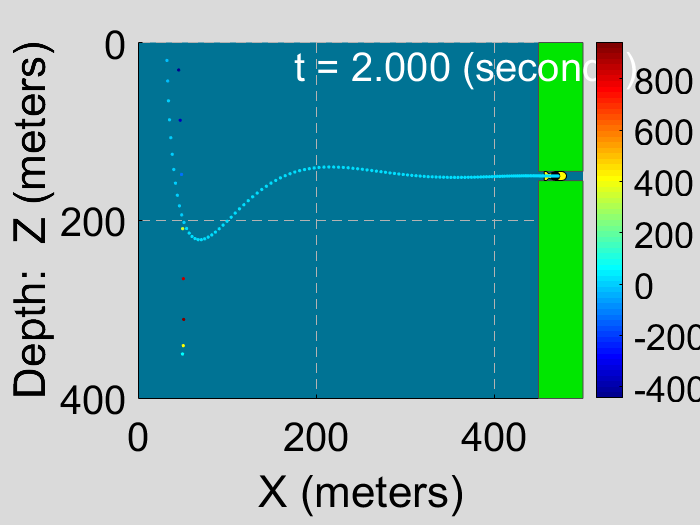

time_vector = 0:0.01:2;
ref_1 = ones(size(time_vector)).* 465;
ref_2 = ones(size(time_vector)).* 150;
ref_3 = zeros(size(time_vector));
initial_condition_sim = [0,0,0,100,50,-300,350,0,45*pi/150,0,0,0,0,0,0];

[y_final_sim,tt,x_final] = lsim(closed_loop_system,[ref_1;ref_2;ref_3],...
    time_vector,initial_condition_sim);
animate_auv(tt,y_final_sim(:,4),y_final_sim(:,5),y_final_sim(:,6),false,10.5)

**We can see from the figure that the submarine enters the tunnel with only 0.5m clearance in under 2 seconds.**

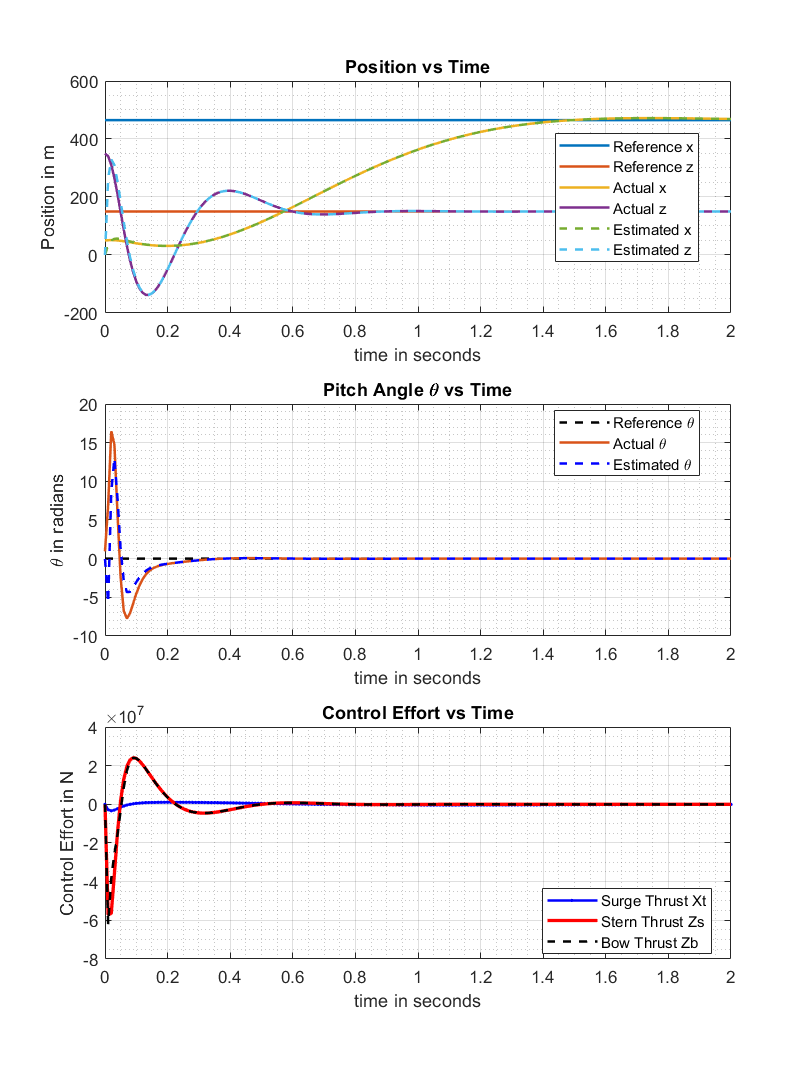


figure(3)
figure('Position',[10,10,900,1200])
subplot(3,1,1)

plot(time_vector,ref_1,'linewidth',1.5)
title('Position vs Time')
grid on
grid minor
hold on
plot(time_vector, ref_2,'linewidth',1.5)
plot(time_vector,y_final_sim(:,4)','linewidth',1.5)
plot(time_vector,y_final_sim(:,5)','linewidth',1.5)
plot(time_vector,y_final_sim(:,7)','--','linewidth',1.5)
plot(time_vector,y_final_sim(:,8)','--','linewidth',1.5)
xlabel('time in seconds')
ylabel('Position in m')
leg=legend('Reference x','Reference z',...
    'Actual x', 'Actual z',...
    'Estimated x', 'Estimated z');
set(leg,'location','best')
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
subplot(3,1,2)
plot(time_vector,ref_3,'--k','linewidth',1.5)
hold on
grid on
grid minor
plot(time_vector,y_final_sim(:,6)','linewidth',1.5)
plot(time_vector,y_final_sim(:,9)','--b','linewidth',1.5)
title('Pitch Angle \theta vs Time')
leg = legend('Reference \theta',...
    'Actual \theta','Estimated \theta');
xlabel('time in seconds')
ylabel('\theta in radians')
set(leg,'location','best')
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
subplot(3,1,3)
plot(time_vector,y_final_sim(:,1)','.-b','linewidth',1.5)
title('Control Effort vs Time')
grid on
grid minor
hold on
plot(time_vector,y_final_sim(:,2)','r','linewidth',2)
plot(time_vector,y_final_sim(:,3)','--k','linewidth',1.5)
xlabel('time in seconds')
ylabel('Control Effort in N')
leg=legend('Surge Thrust Xt', 'Stern Thrust Zs','Bow Thrust Zb');
set(leg,'location','best')

## Conclusion:

                Thus, the final Integrated system is constructed that follows the reference trajectory that is given as input from, say a Motion Planning Module. We can clearly see from the final simulation that all the constraints for the Bonus Question has also been satisfied by the Final Design. 